# World Cup™ Goals

## 1.

Load `WCgoals.mat`. This file contains a record of the number of goals and number of matches played in each FIFA World Cup™.

load WCgoals.mat

## 2.

Make a plot of the average number of goals per match, as a function of year.

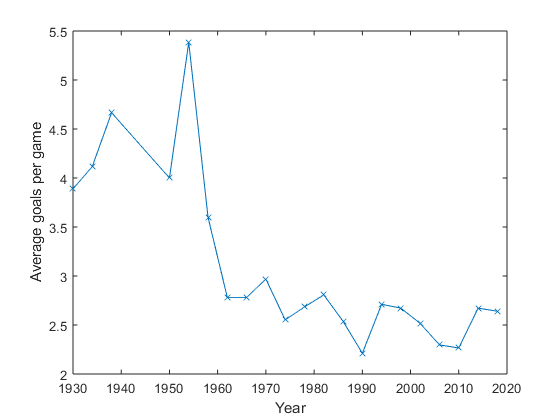

plot(Yr,avgGoals,'x-')
xlabel('Year')
ylabel('Average goals per game')

## 3.

Calculate two best-fit trendlines: one for the entire data set, and the other for just the World Cups from 1962 onward. Overlay both lines on the plot.

fit1 = fitlm(Yr,avgGoals)

fit1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________
    (Intercept)       51.998       9.3028     5.5895    2.1686e-05
    x1             -0.024743    0.0047055    -5.2585     4.478e-05

Number of observations: 21, Error degrees of freedom: 19
Root Mean Squared Error: 0.561
R-squared: 0.593,  Adjusted R-Squared 0.571
F-statistic vs. constant model: 27.7, p-value = 4.48e-05

fit2 = fitlm(Yr(Yr >= 1962),avgGoals(Yr >= 1962))

fit2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE        tStat      pValue 
                   __________    ________    _______    ________
    (Intercept)         14.66      5.7076     2.5684    0.023363
    x1             -0.0060568    0.002868    -2.1118    0.054628

Number of observations: 15, Error degrees of freedom: 13
Root Mean Squared Error: 0.192
R-squared: 0.255,  Adjusted R-Squared 0.198
F-statistic vs. constant model: 4.46, p-value = 0.0546

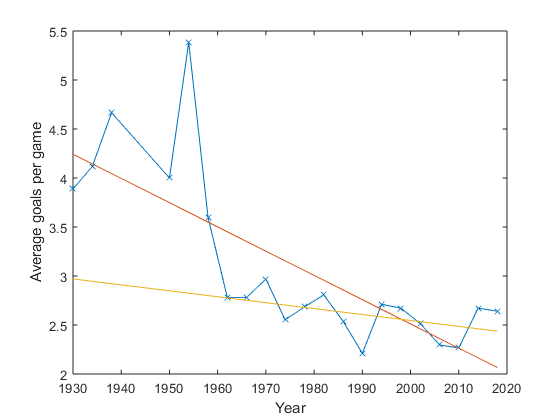


hold on
plot(Yr,predict(fit1,Yr))
plot(Yr,predict(fit2,Yr))
hold off

## 4

Make normal probability plots of the residuals from both fits. Are the residuals normally distributed?

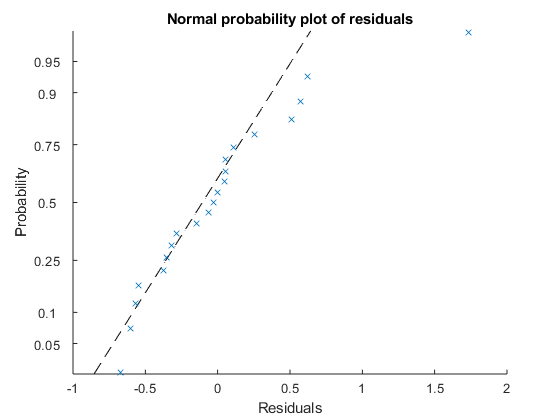

plotResiduals(fit1,'probability')

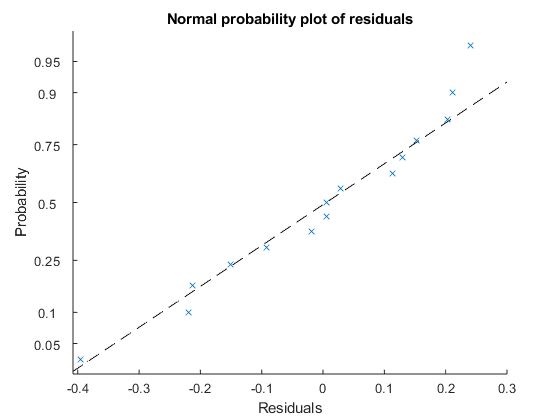

plotResiduals(fit2,'probability')

## 5

Predict the average number of goals per match in the World Cup™ 2022 from the fitted trendlines. Do you trust the predictions?

goals2022_1 = predict(fit1,2022)

goals2022_1 = 1.9667

goals2022_2 = predict(fit2,2022)

goals2022_2 = 2.4128